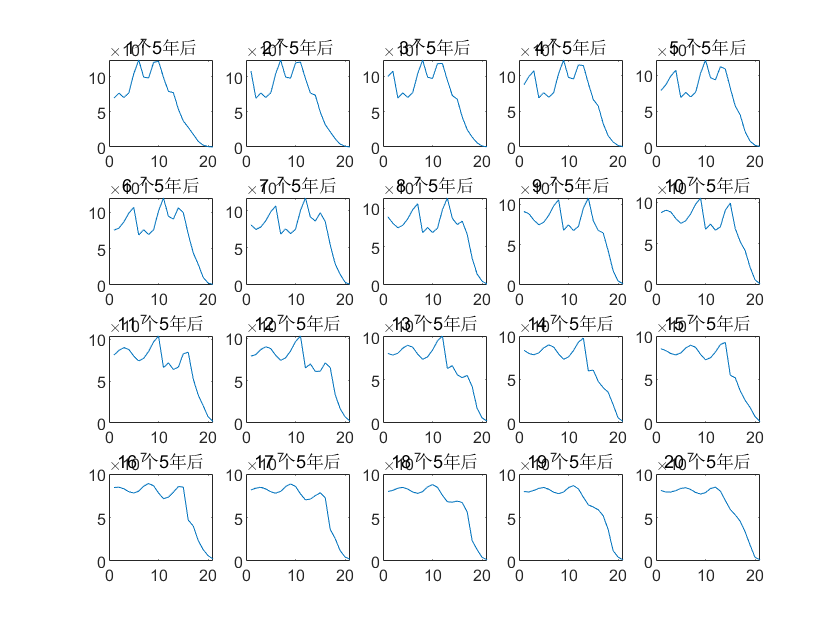

clear;
D=load('./dataforpeoplenumber.txt');
D2=load('./datafortruepredict.txt');
DR=(D(:,2));
BR=(D(:,3));
BR2=(D2(:,3));
%各个年龄段人口数量，20*5，100年数据
N=zeros(21,20);
N(:,1)=specific_people(D(:,1),DR,BR);
subplot(4,5,1);
plot(N(:,1));
title('1个5年后');
%10年后
N(:,2)=specific_people(N(:,1),DR,BR2);
subplot(4,5,2);
plot(N(:,2));
title('2个5年后');
N(:,3)=specific_people(N(:,2),DR,BR2);
subplot(4,5,3);
plot(N(:,3));
title('3个5年后');
N(:,4)=specific_people(N(:,3),DR,BR2);
subplot(4,5,4);
plot(N(:,4));
title('4个5年后');
for i=5:1:20
    N(:,i)=specific_people(N(:,i-1),DR,BR2);
    subplot(4,5,i);%4*5网格
    plot(N(:,i));
    title([num2str(i),' 个5年后']);
end

%%总人口变化
figure;
M=sum(N)

M =                 1366556712                1432123352                1480021279                1505861307                1512605069                1505114211                1493462169                1481502480                1466101039                1444864941                1418905011                1393916219                1374018314                1362110313                1357828884                1357561394                1356296440                1352092179                1345118827                1337885973


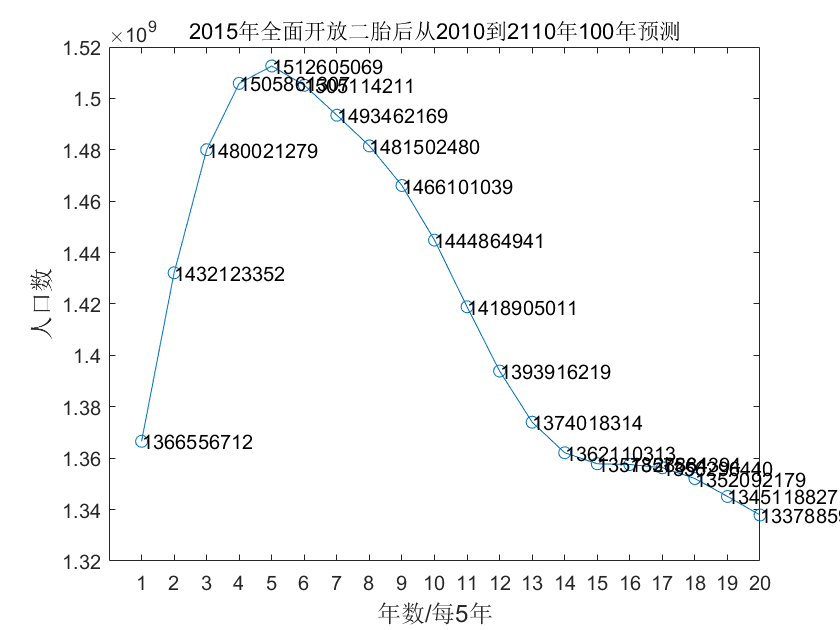

plot(M,'-o');
title('2015年全面开放二胎后从2010到2110年100年预测')
set(gca,'XTick',1:1:20);
N0=ones(21,1)*1300000000;
t=size(M,2);
for i=1:1:t
    text(i,M(1,i),num2str(M(1,i)));
end
%D各年龄段人口DR各年龄段死亡率BR各年龄段出生率
xlabel('年数/每5年', 'fontsize',12)
ylabel('人口数','fontsize',12)

function [N]=specific_people(D,DR,BR)
N=zeros(21,1);
for i=21:(-1):1
    if i==1
        b=0;
        for j=1:1:21
            b=b+round(D(j,1)*BR(j,1)/1000);
        end
        
        N(i,1)=round(b*(1-DR(1,1)/1000)^4+b*(1-DR(1,1)/1000)^3+b*(1-DR(1,1)/1000)^2+b*(1-DR(1,1)/1000)+b);
    else if i==21
            N(i,1)=round(D(i,1)*(1-DR(i,1)/1000)^5+D(i-1,1)*(1-DR(i-1,1)/1000)^5);
    else
        N(i,1)=round(D(i-1,1)*(1-DR(i-1,1)/1000)^5);
    end
    end
end
end
